clear;
clc;
close all;

Fs = 1000*1000;
T = 1/Fs;
L = 4000;
t = (0:L-1)*T;

Am = 1;
Ac = 3;
Fm = 2*1000;
Fc = 10*1000;
Wc = 2*pi*Fc;
Wm = 2*pi*Fm;
kp = 2*pi;

m = Am*sin(Wm*t);
c = Ac*sin(Wc*t);
mup = Am*kp;

x = mup*cos(Wm*t);
y = Ac*cos(Wc*t+x); %phase modulated wave

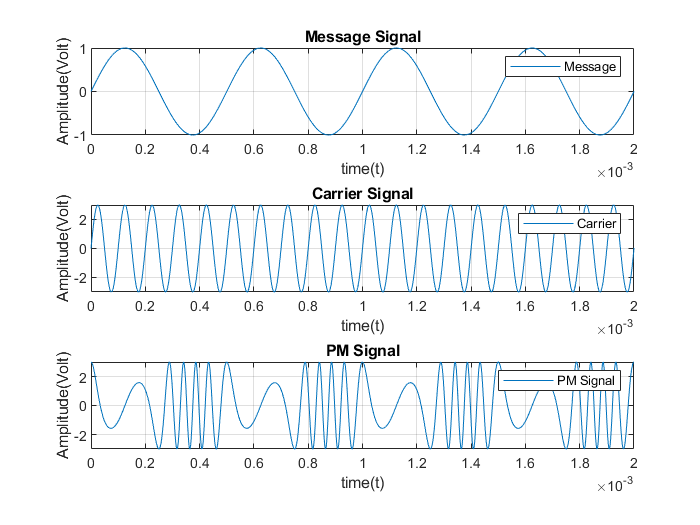

% Part A Modulation
figure(1);
    subplot(3, 1, 1);
    plot(t, m);
    title('Message Signal');
    xlabel('time(t)');
    ylabel("Amplitude(Volt)");
    legend("Message");
    xlim([0 4/Fm]);
    grid;

    subplot(3, 1, 2);
    plot(t, c);
    title('Carrier Signal');
    xlabel('time(t)');
    ylabel("Amplitude(Volt)");
    legend("Carrier");
    xlim([0 4/Fm]);
    grid;

    subplot(3, 1, 3);
    plot(t, y);
    title('PM Signal');
    xlabel('time(t)');
    ylabel("Amplitude(Volt)");
    legend("PM Signal");
    xlim([0 4/Fm]);
    grid;



% Frequency Spectrum
f = Fs * (-L/2:(L/2-1)) / L;

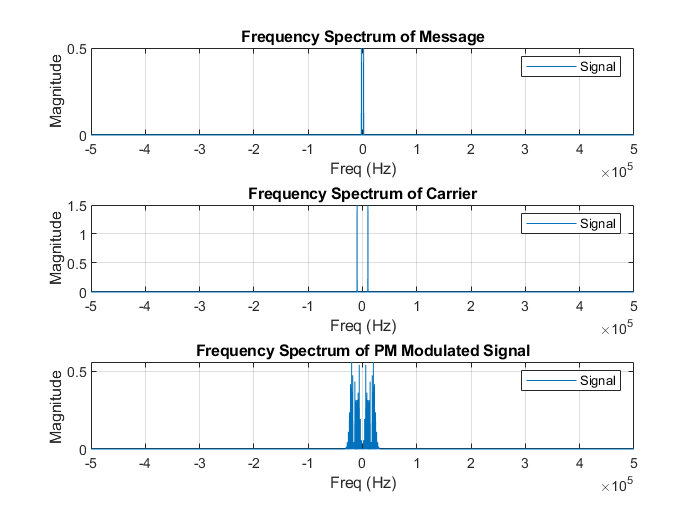

figure(2);
    M = fftshift( fft(m) );
    M = abs(M/L);
    subplot(311);
    plot(f, M);
    title('Frequency Spectrum of Message');
    xlabel("Freq (Hz)");
    ylabel("Magnitude");
    legend("Signal");
    grid;

    C = fftshift( fft(c) );
    C = abs(C/L);    
    subplot(312);
    plot(f, C);
    title('Frequency Spectrum of Carrier');
    xlabel("Freq (Hz)");
    ylabel("Magnitude");
    legend("Signal");
    grid;

    Y = fftshift( fft(y) );
    Y = abs(Y/L);
	subplot(313);
    plot(f, Y);
    title('Frequency Spectrum of PM Modulated Signal');
    xlabel("Freq (Hz)");
    ylabel("Magnitude ");
    legend("Signal");
    grid;

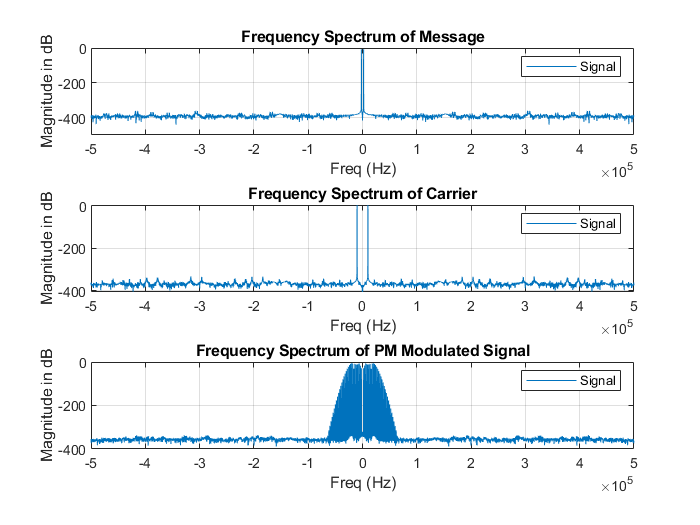

figure(3);   
    subplot(311);
    plot(f, 10*log(M) );
    title('Frequency Spectrum of Message');
    xlabel("Freq (Hz)");
    ylabel("Magnitude in dB");
    legend("Signal");
    grid;


    subplot(312);
    plot(f, 10*log(C) );
    title('Frequency Spectrum of Carrier');
    xlabel("Freq (Hz)");
    ylabel("Magnitude in dB");
    legend("Signal");
    grid;


	subplot(313);
    plot(f, 10*log(Y) );
    title('Frequency Spectrum of PM Modulated Signal');
    xlabel("Freq (Hz)");
    ylabel("Magnitude in dB");
    legend("Signal");
    grid;

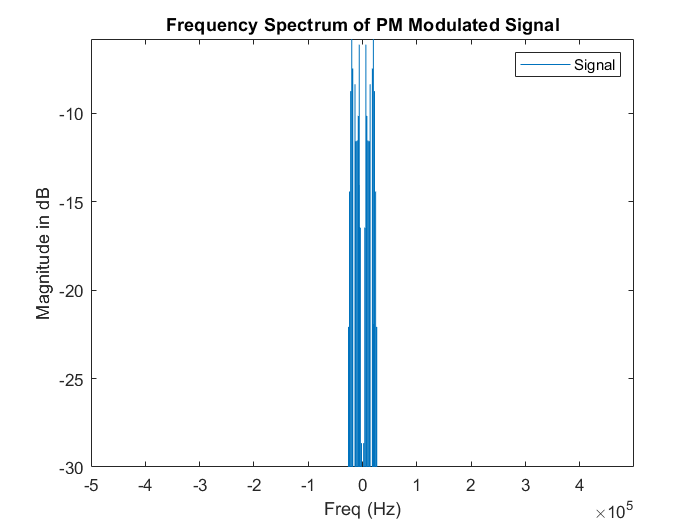

    
figure(6);
    plot(f, 10*log(Y) );
    title('Frequency Spectrum of PM Modulated Signal');
    xlabel("Freq (Hz)");
    ylabel("Magnitude in dB");
    legend("Signal");
    axis([-inf inf -30 inf]);

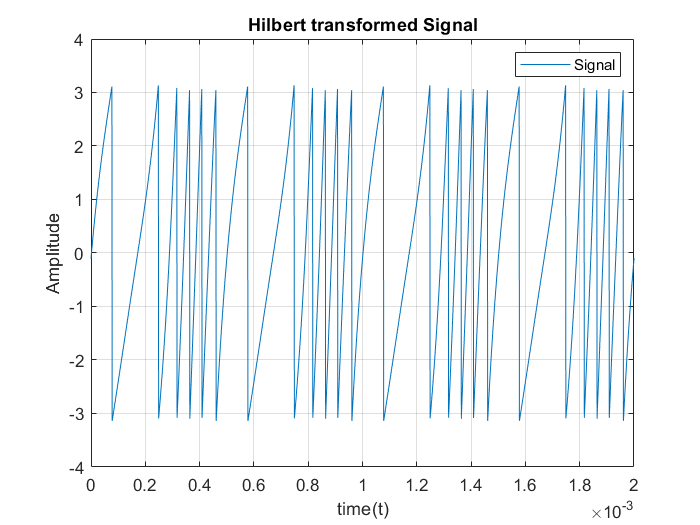

h_y = angle(hilbert(y));
figure();
plot(t,h_y);
title('Hilbert transformed Signal');
xlabel('time(t)');
ylabel("Amplitude");
legend("Signal");
xlim([0 4/Fm]);
grid;

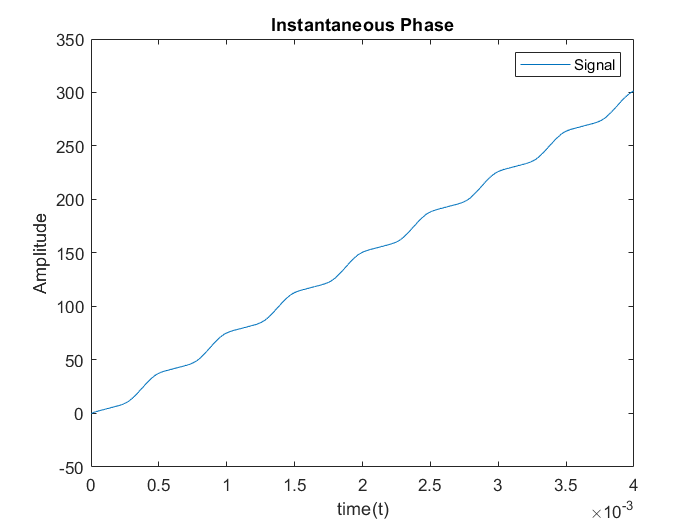

instantaneous_phase = unwrap(h_y);
figure();
plot(t,instantaneous_phase);
title('Instantaneous Phase');
xlabel('time(t)');
ylabel("Amplitude");
legend("Signal");
xlim([0 8/Fm]);

msg_dem = (instantaneous_phase - 2*pi*Fc*t);

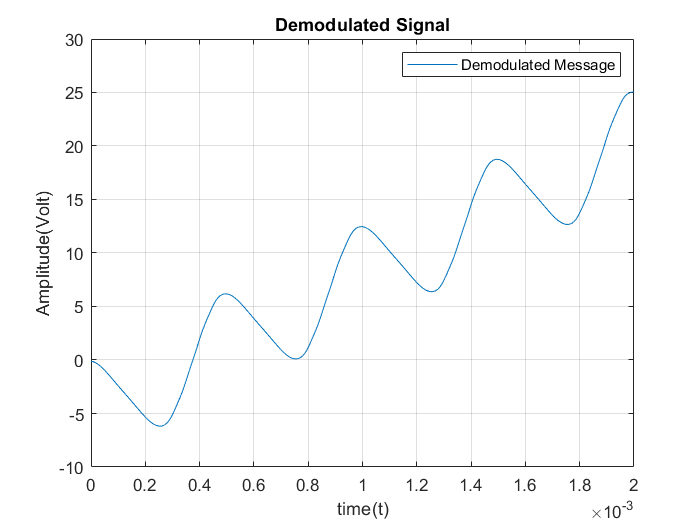

figure();
    plot(t,msg_dem);
    title('Demodulated Signal');
    xlabel('time(t)');
    ylabel("Amplitude(Volt)");
    legend("Demodulated Message");
    xlim([0 4/Fm]);
    grid;

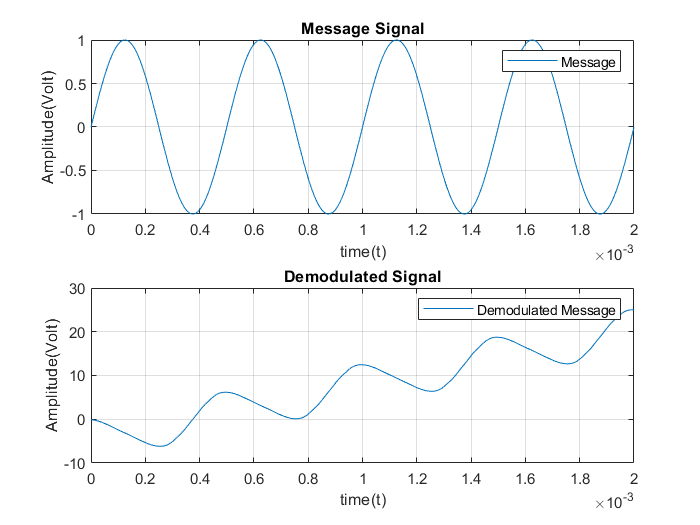

figure(4);
subplot(212);
    plot(t,msg_dem);
    title('Demodulated Signal');
    xlabel('time(t)');
    ylabel("Amplitude(Volt)");
    legend("Demodulated Message");
    xlim([0 4/Fm]);
    grid;
subplot(211);
    plot(t,m);
    title('Message Signal');
    xlabel('time(t)');
    ylabel("Amplitude(Volt)");
    legend("Message");
    xlim([0 4/Fm]);
    grid;

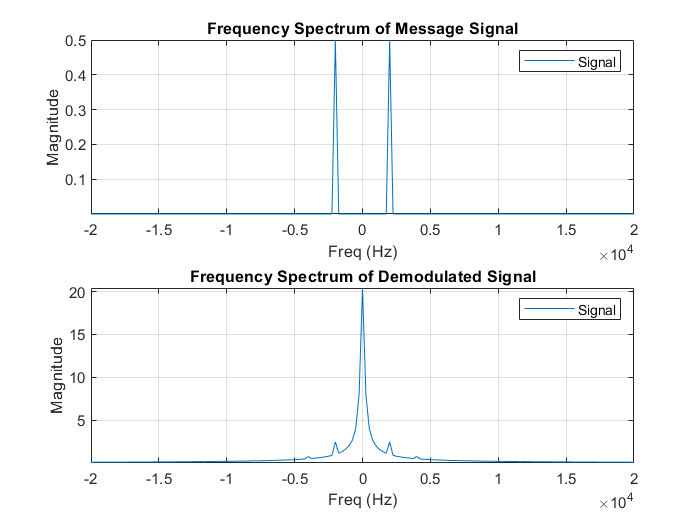

figure(5);
    subplot(212);
        plot(f,abs(fftshift(fft(msg_dem)))/L);
        title('Frequency Spectrum of Demodulated Signal'); 
        xlabel("Freq (Hz)");
        ylabel("Magnitude");
        legend("Signal");
        axis([-20*1000 20*1000 -inf inf]);
        grid;
        
    subplot(211);
        plot(f,abs(fftshift(fft(m)))/L);
        title('Frequency Spectrum of Message Signal'); 
        xlabel("Freq (Hz)");
        ylabel("Magnitude");
        legend("Signal");
        axis([-20*1000 20*1000 -inf inf]);
        grid;

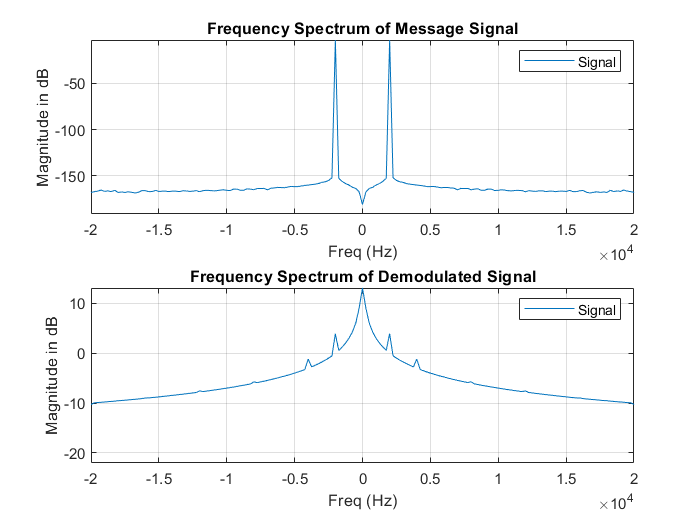

figure(5);
    subplot(212);
        plot(f,10*log10(abs(fftshift(fft(msg_dem)))/L));
        title('Frequency Spectrum of Demodulated Signal'); 
        xlabel("Freq (Hz)");
        ylabel("Magnitude in dB");
        legend("Signal");
        axis([-20*1000 20*1000 -inf inf]);
        grid;
    
    subplot(211);
        plot(f,10*log10(abs(fftshift(fft(m)))/L));
        title('Frequency Spectrum of Message Signal'); 
        xlabel("Freq (Hz)");
        ylabel("Magnitude in dB");
        legend("Signal");
        axis([-20*1000 20*1000 -inf inf]);
        grid;